## **散布図と近似直線**

グラフに近似直線を追加したいときは，以下のように書きます．

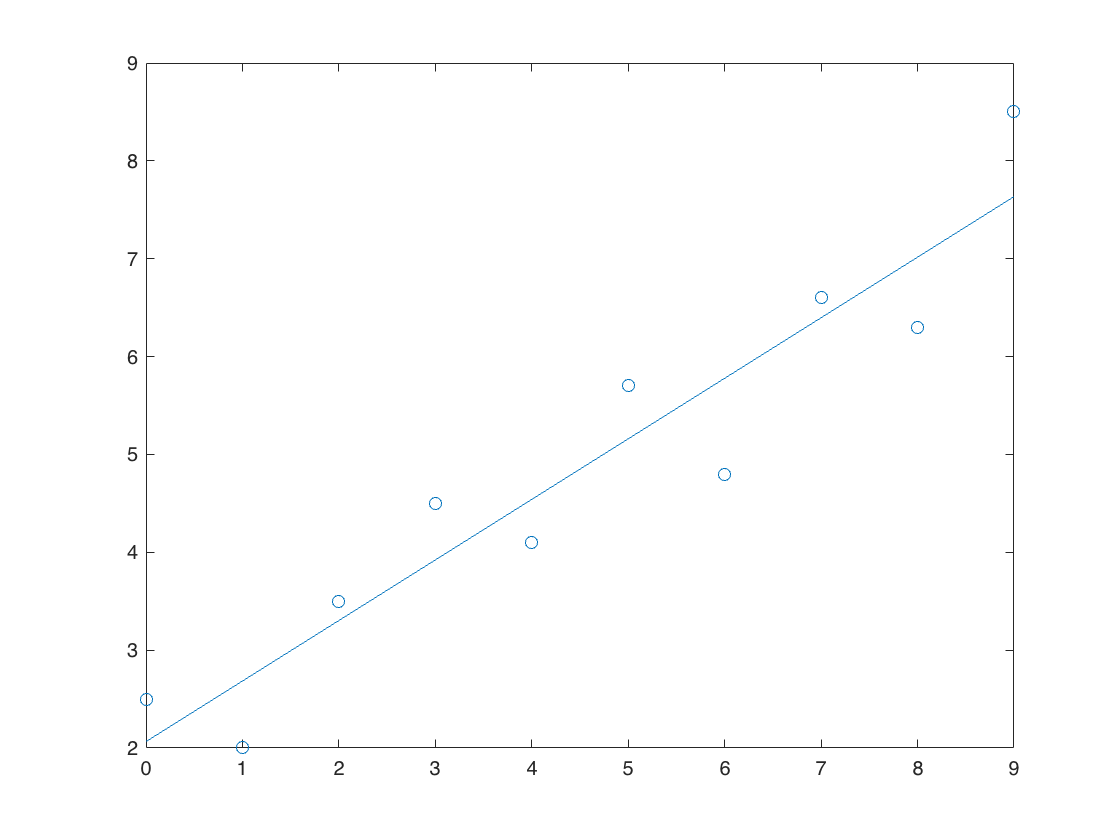

x = 0:9;
y = [2.5 2 3.5 4.5 4.1 5.7 4.8 6.6 6.3 8.5];

figure
plot(x,y,'o') % 散布図を作る
lsline % 近似直線を引く

または以下のように書きます．

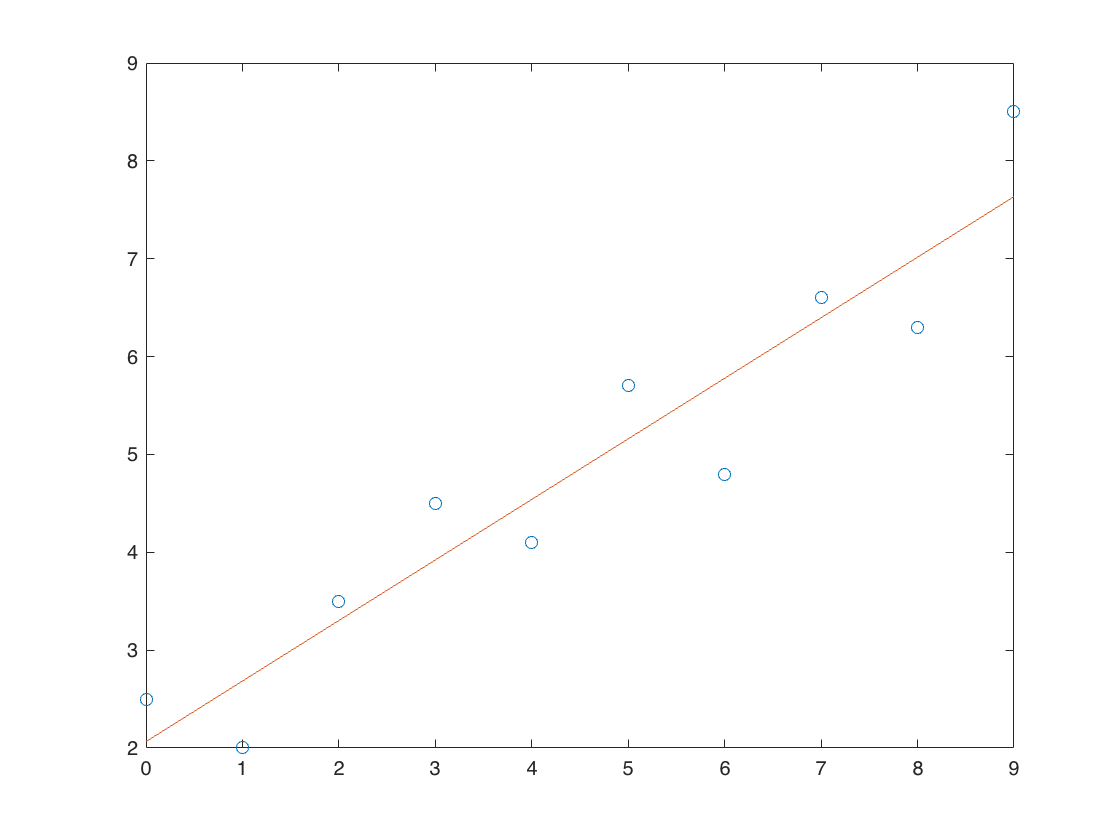

figure
plot(x,y,'o')
p = polyfit(x,y,1);
x1 = linspace(0,9);
y1 = polyval(p,x1);
hold on
plot(x1,y1) % 近似直線を引く
hold off

参考：[`plot`](matlab:doc('plot'))，[`lsline`](matlab:doc('lsline'))，[`polyfit`](matlab:doc('polyfit')), [`polyval`](matlab:doc('polyval'))

## 近似直線とは？

近似直線とはデータを一番近く表す直線のことを言います。

では「一番近く」とはどういう意味でしょう。[`polyfit`](matlab:doc('polyfit')) のドキュメンテーションを見ると、「最小二乗的に」という単語があります。

近似直線を求める上で一般的に使われるのは最小二乗法という手法であり、それは直線とデータの**残差の二乗和**を最小にする様に直線を定義するものです。

下記のグラフを見てみましょう。データ（青い**〇**）と近似直線（赤い実線）があります。データと近似直線の差（黒い点線）を**残差**といいます。また、残差の二乗和は「残差を二乗してその和を計算する」という意味で、以下のように定義されます。

**残差の二乗和** = ${\left(2\ldotp 5-2\ldotp 1\right)}^2 +{\left(2-2\ldotp 7\right)}^2 +{\left(3\ldotp 5-3\ldotp 3\right)}^2 +{\left(4\ldotp 5-3\ldotp 9\right)}^2 +\cdots$

（ちなみに、なぜ二乗をとると思いますか？）

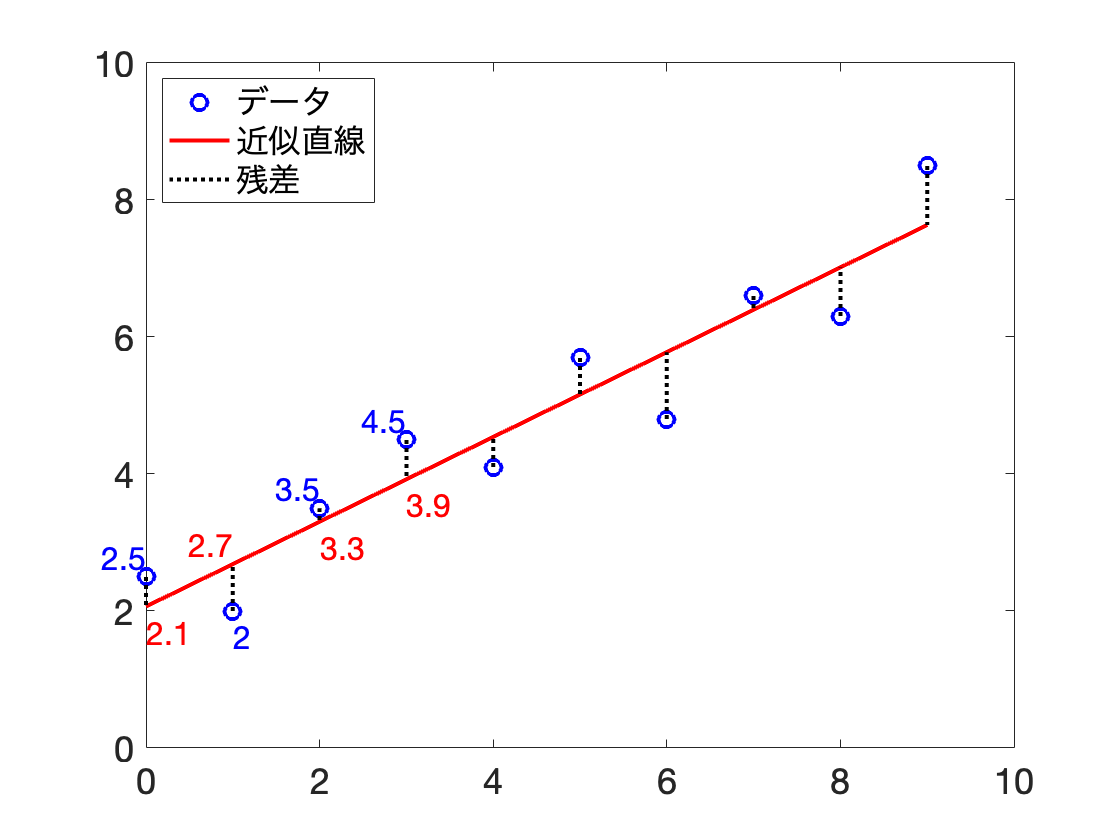

アニメーションにあるように、直線によっては残差の量は変わってきます。**最小二乗法とはこの残差の二乗の和を最小にする直線を求める手法です。**

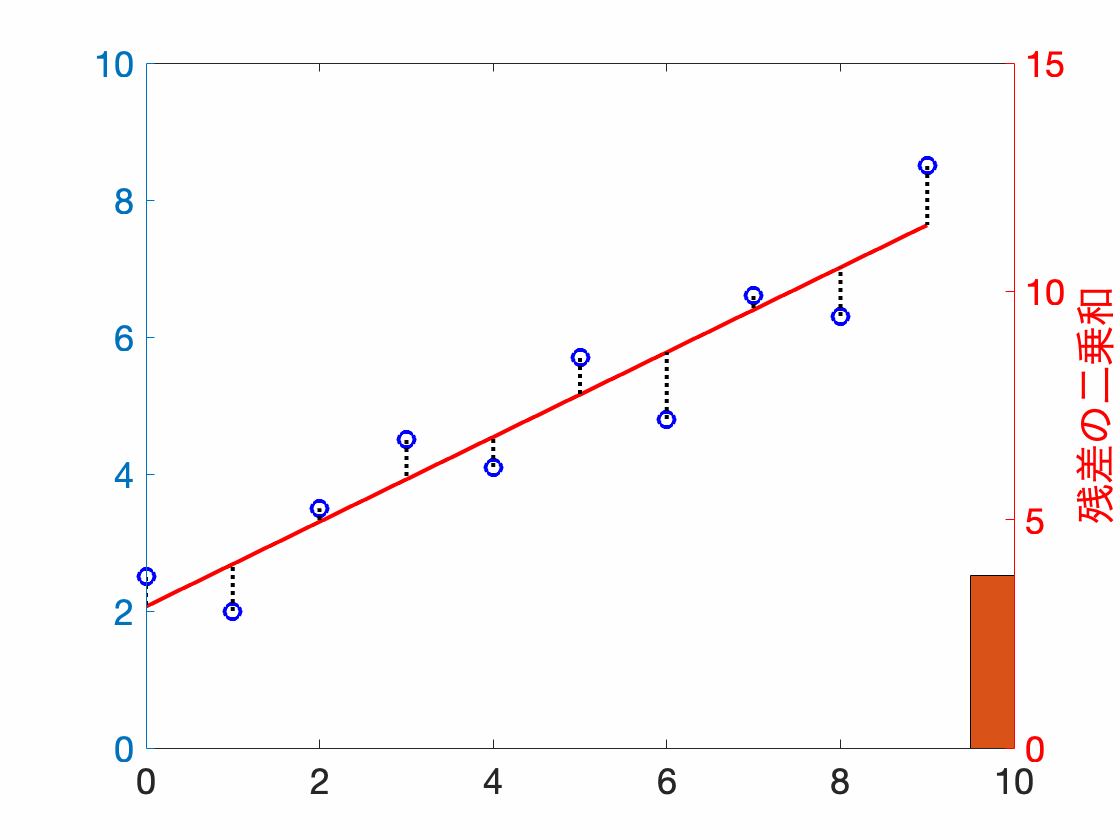

[Mission3に戻る](matlab:closeAndMove("sbda_mission3.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.